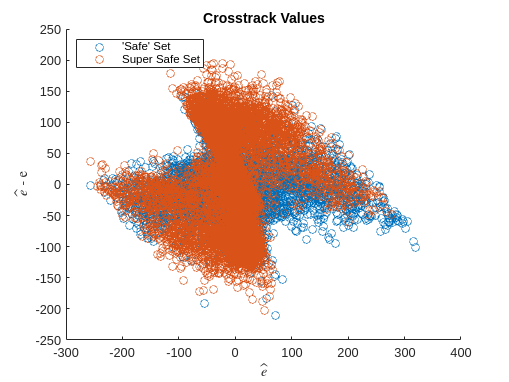

clear variables; close all; clc;

csvDataSafe_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/safe/2024-7-11/generated_states.csv");
csvDataSafe_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/safe/2024-7-11/combined_states.csv");
error_NN_h_safe = csvDataSafe_c.error_h;
error_NN_y_safe = csvDataSafe_c.error_y;
y_safe = csvDataSafe_c.y;
y_pred_safe = csvDataSafe_g.y_err;
h_pred_safe = csvDataSafe_g.h_err_NN;
x_safe = csvDataSafe_c.x;
h_safe = csvDataSafe_c.h;



csvDataUnsafe_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/unsafe/2024-7-11/generated_states.csv"); %50m, OOD by 0
csvDataUnsafe_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/unsafe/2024-7-11/combined_states.csv");

error_h_unsafe = csvDataUnsafe_c.error_h; %NN Error, height offset 
error_y_unsafe = csvDataUnsafe_c.error_y; %NN Error, crosstrack offset 
ehat_h_unsafe = csvDataUnsafe_g.h_err_NN; %NN Output- Predicted height offset
ehat_y_unsafe = csvDataUnsafe_g.y_err;

% scatter(error_h_unsafe, ehat_h_unsafe);
% hold on;
% xlabel('$$\hat{e}$$','Interpreter','Latex');
% ylabel('$\hat{e}$ - e','Interpreter','Latex');
% hold off;
% 
% scatter(error_y_unsafe, ehat_y_unsafe);

error_NN_h_unsafe = csvDataUnsafe_c.error_h; %NN Error, height offset 
error_NN_y_unsafe = csvDataUnsafe_c.error_y; %NN Error, crosstrack offset 
y_unsafe = csvDataUnsafe_c.y;
y_pred_unsafe = csvDataUnsafe_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_unsafe = csvDataUnsafe_g.h_err_NN; %NN Output- Predicted height offset
h_true_unsafe = csvDataUnsafe_g.h_err_true; %True height error based on state info 

%True State Information 
x_unsafe = csvDataUnsafe_c.x; %Horizontal distance from runway 
h_unsafe = csvDataUnsafe_c.h; %True Height (Altitude relative to runway) 

scatter(error_NN_y_unsafe, y_pred_unsafe);
hold on; 
scatter(error_NN_y_safe, y_pred_safe);
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Crosstrack Values");
legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
hold off;

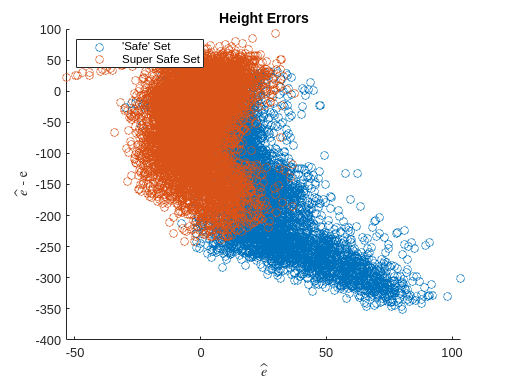


scatter(error_NN_h_unsafe, h_pred_unsafe);
hold on; 
scatter(error_NN_h_safe, h_pred_safe);
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("Height Errors");
legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
hold off;

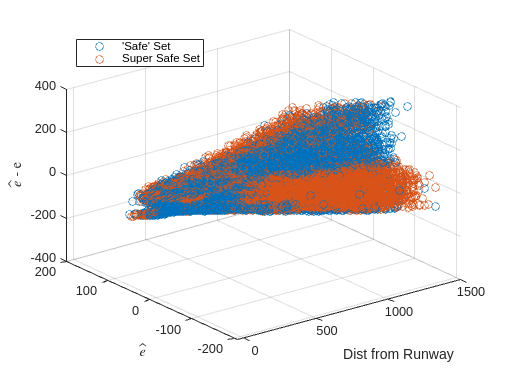


scatter3(x_unsafe, y_pred_unsafe, error_NN_y_unsafe);
hold on;
scatter3(x_safe, y_pred_safe, error_NN_y_safe);
xlabel("Dist from Runway")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
hold off;

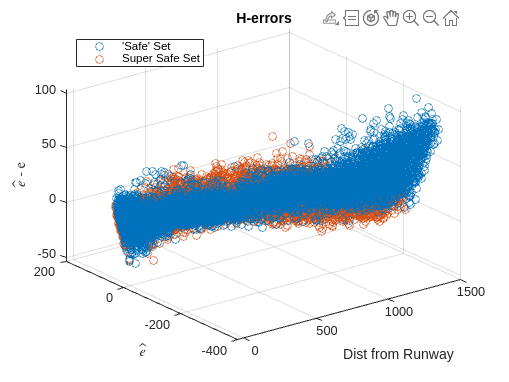


scatter3(x_unsafe, h_pred_unsafe, error_NN_h_unsafe);
hold on;
scatter3(x_safe, h_pred_safe, error_NN_h_safe);
xlabel("Dist from Runway")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
legend({"'Safe' Set", "Super Safe Set"}, 'Location', 'northwest');
title("H-errors");
hold off;



% scatter3(y_safe, y_pred_safe, error_NN_y_safe, "red");
% hold on;
% xlabel("Crosstrack Pos")
% ylabel('$$\hat{e}$$','Interpreter','Latex');
% zlabel('$\hat{e}$ - e','Interpreter','Latex');
% hold off;

% scatter3(h_safe, y_pred_safe, error_NN_y_safe, "red"); 
% hold on;
% xlabel("Height")
% ylabel('$$\hat{e}$$','Interpreter','Latex');
% zlabel('$\hat{e}$ - e','Interpreter','Latex');
% hold off;
% 
